Joseph Ntaimo, Feb 2024 | Roberto Bolli, Kaleb Blake Feb 2025

# 2.12 Lab 4 Motor Modeling

## ***Whenever you see a blue line, you've reached the end of a section. Click on the current section and hit "run section" before continuing.***

### Motor Parameters

We are using a Modern Robotics 12DC Motor with a 60RPM Planetary gearset.

Look at the motor page (https://www.gobilda.com/modern-robotics-12vdc-motor/) to fill in the following:

- Motor stall torque constant $K_{t,\;\textrm{stall}}$

- Back EMF Constant $\textrm{Ke}$

- Estimated nominal torque 

- Gear ratio $r$

#### Electrical Constants

Motor torque constant

t_stall = ...; %kg*cm, from webpage
t_stall_Nm = t_stall *...; % Convert from kg*cm to N*m
stall_current = ...; %(A) Stall current of the motor 
Kt_stall = (t_stall_Nm)/stall_current %(Nm/A) motor torque constant

Incorrect use of '=' operator. Assign a value to a variable using '=' and compare values for equality using '=='.

Kt_stall = 200

Back EMF Constant

V = ...; %(v) Nominal voltage of the motor 
RPM = ...; % Tested no-load speed @ 12VDC (RPM) 
rad_per_sec = RPM*...; %Convert from RPM to rad/sec
Ke = V/(rad_per_sec) %(V/(rad/s))

Ke = 0.0198

In an ideal motor, Kt = Ke. But since we are using actual measured values, we set our "real" Kt to be the average of Kt_stall and Ke. Implement that below.

Kt = ...; %(Nm/a) or (V/(rad/s))

We are using a 60 RPM planetary gearbox (https://www.gobilda.com/5202-series-yellow-jacket-planetary-gear-motor-99-5-1-ratio-24mm-length-6mm-d-shaft-60-rpm-36mm-gearbox-3-3-5v-encoder/). Input the gear ratio below. Hint: gear ratios expressed as x:1 should be written as r=x in Matlab.

r = ...; %gear ratio 

Armature resistance

R = 1.3; %(Ohms) Armature resistance

#### Mechanical Constants

Look at the motor page(s) and use the pre-filled parameters to fill in the following

- Rotor volume $v_{\textrm{rotor}}$

- Rotor mass $m_{\textrm{rotor}}$

- Rotor inertia $I_{\textrm{rotor}}$

Motor Rotor inertia

r_rotor = 1/8*25.4/1000/2; %(m)radius of the rotor
l_rotor = 0.075; %(m) approx length of rotor
rho_rotor = 7.75;%(kg/m^3) density of steel rotor
v_rotor = ... %(m^3) volume of rotor
m_rotor = ...; %(kg) mass of rotor
I_rotor = ... % Assume the rotor is a point mass rotating at a distance r_rotor from the axis of rotation. Units: kgm^2

v_rotor = 5.9380e-07

I_rotor = 1.1598e-11

Motor and link parameters 

m_motor = 0.486; %(kg) mass (weight) of the motor
r_motor = 0.036/2;%(m) radius of the motor
m_arm = 0.059; %(kg) mass of a single arm
Lhole = 0.024; %(m) distance between large holes on the arm
L1 = Lhole*7; %(m) length of first linkage
L2 = Lhole*9; %(m) length of second linkage
L = 0.216; %(m) length of full C channel

Hint - you will need the [parallel axis theorem](https://en.wikipedia.org/wiki/Parallel_axis_theorem) and some useful [moments of inertia](https://en.wikipedia.org/wiki/List_of_moments_of_inertia)

Il_2 = ... %(kgm^2) Load moment of inertia for second motor. Model as thin rod rotating about one end. Variables: arm mass, length of second linkage
Im = ... ; %(kgm^2) Motor moment of inertia. Model as solid cylinder. Variables: motor mass, motor radius
Il_1 = Im + (motor 2 reflected to base joint, using the parallel axis theorem.) + 1/3*m_arm*L1^2 + (1/12*m_arm*L2^2 + m_arm*(L1+L2/2)^2)%(kgm^2) Load moment of inertia for first motor

Il_2 = 9.1757e-04

Il_1 = 0.0170

Answer the following

- What is the ratio between the two inertias? $\frac{I_{\textrm{L1}} }{I_{\textrm{L2}} }$

- Why is this ratio so large?

- What does this ratio say about the amount of gain your motors will need to move quickly? Which motor should have notably higher gains?

# Checkoff 1

Inertia_ratio = Il_1/Il_2

Inertia_ratio = 18.5405

Viscous damping (e.g. due to friction between gear teeth). We assume there isn't any.

b = 0.00; %(Nm/(rad/s)) Viscous damping

#### Derived parameters

Motor constant

Km = Kt/sqrt(R) %(Nm/w^1/2)

Km = 0.0155

Effective inertia

I1 = Il_1 + r^2*I_rotor %(kgm^2)

I1 = 0.0170

I2 = Il_2 + r^2*I_rotor

I2 = 9.1768e-04

Effective damping

B = b + r^2*Km^2 %(Nm/(rad/s))

B = 2.3902

Input gain

k = r*Kt/R %(Nm/v)

k = 1.3559

Let's make the transfer function!

m1 = generateMotorModel(I1, k, B);
m2 = generateMotorModel(I2, k, B);

Let's take a look at the poles and zeros on the root locus. This can give us insight into how to control this system.

- Is Kp control stable?

- What happens to the closed loop natural frequency of the system as kp increases?

- What happens to damping as kp increases?

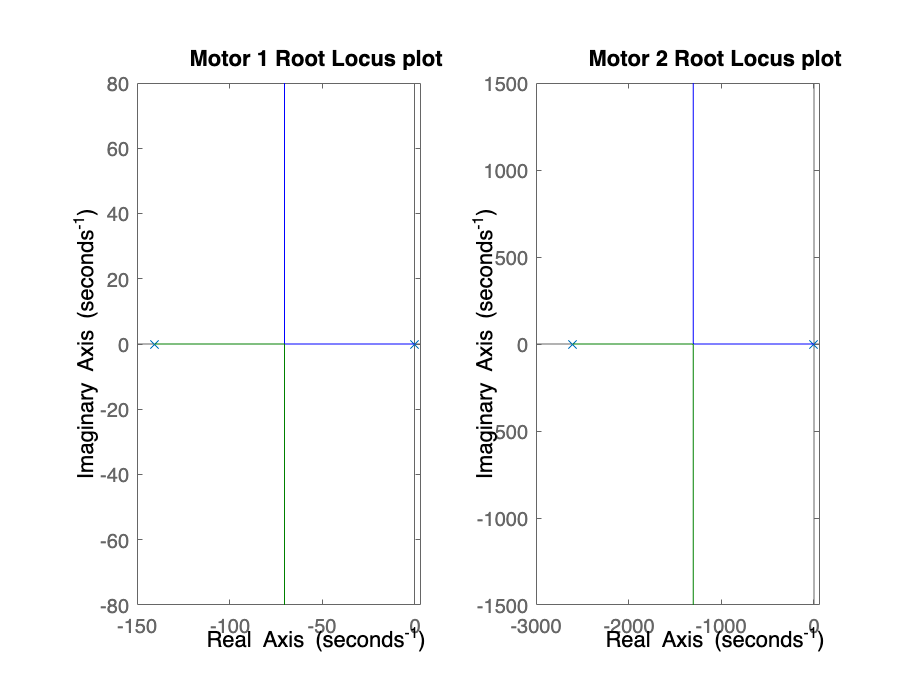

figure;
subplot(1,2,1);
rlocus(m1)
title("Motor 1 Root Locus plot");
subplot(1,2,2);
rlocus(m2);
title("Motor 2 Root Locus plot")

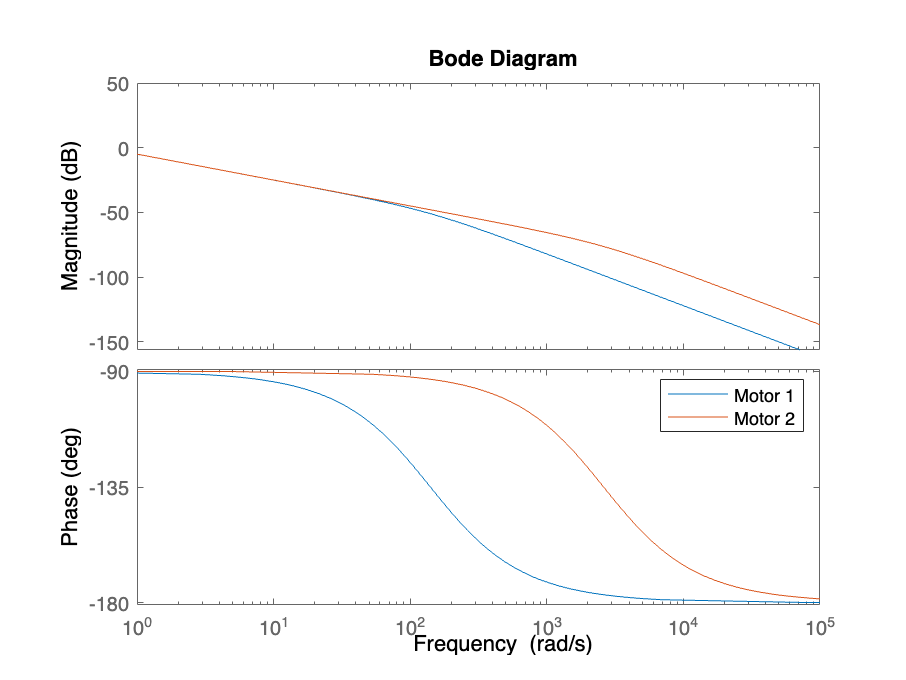

figure;
bode(m1)
hold on
bode(m2);
legend("Motor 1", "Motor 2")
hold off

### Time Responses

Let's see how fast these motors respond to an open loop step in voltage and assess if it makes sense

Since the motors will continuously rotate due to a step in voltage, reading position doesn't make much sense because it will keep increasing. 

- Instead of having position as the output of the step, what is a simple way to make the output velocity? Implement it. (Hint: we're in the Laplace domain)

- How can you make a step of 12V for the motor? (Hint: what variable stores the motor voltage?)

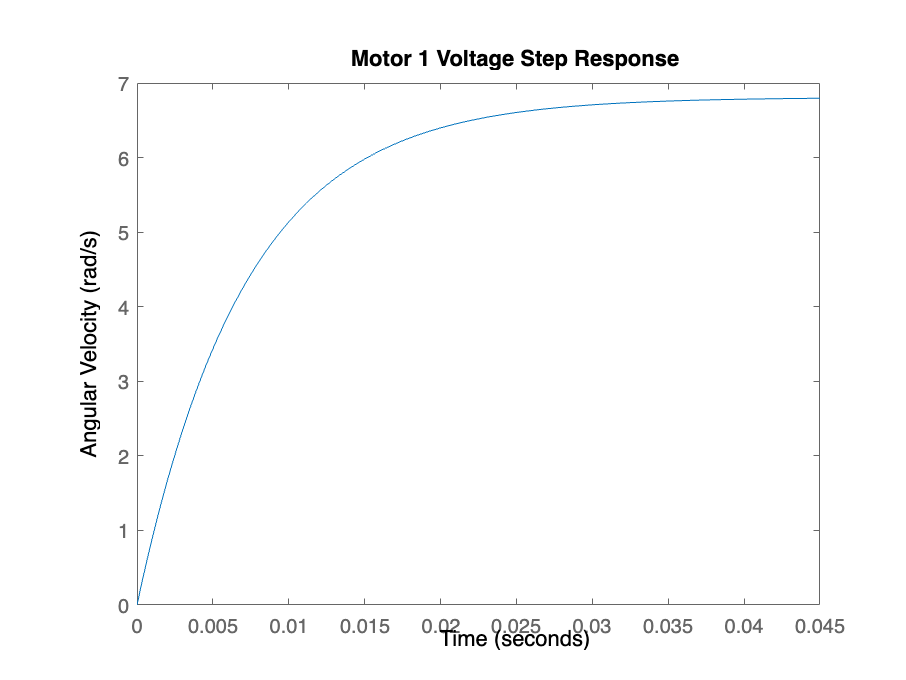

s = tf('s');
step(...*...*m1);
title("Motor 1 Voltage Step Response")
ylabel("Angular Velocity (rad/s)")

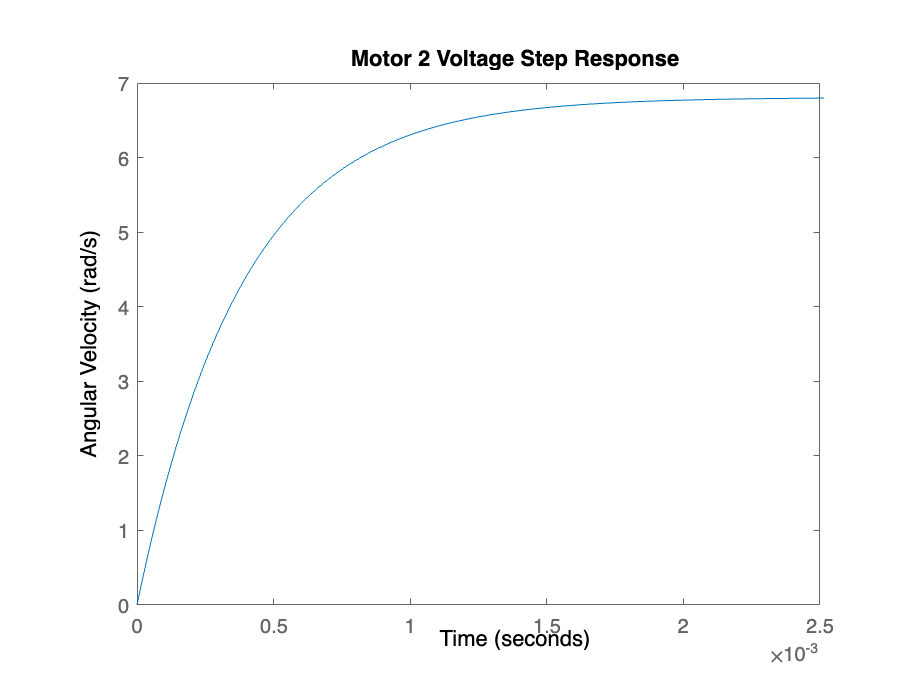

step(...*...*m2);
title("Motor 2 Voltage Step Response")
ylabel("Angular Velocity (rad/s)")

- Does the steady state velocity make sense for the motor given it's RPM rating? 

- How could you adjust your model to make the steady state velocity make sense? (Hint - Kt)

- From the step response, what is the approximate time constant estimate for both of the motors (time to reach 63.2% of no-load speed)?

Helpful equation $V_{\textrm{RPM}} =\frac{V_{\frac{\textrm{rad}}{s}} \cdot 60}{2\cdot \pi }$.

Let's overlay the plots to compare the speeds of the motors

figure;
hold on;
step(s*m1*V);
step(s*m2*V);
title("Dual motor voltage step response");
legend("Motor 1", "Motor 2");
ylabel("Angular Velocity (rad/s)");
hold off;

- Which motor is faster?

- Does that make sense? Why?

# Checkoff 2

## Controller 1 design time!

We are going to design a controller for the first joint using a lead compensator (essentially a PD controller with a targeted frequency range) and proportional controller.

Let's pick a conservative crossover frequency:

wc = 100;

How does the plant look without compensation?

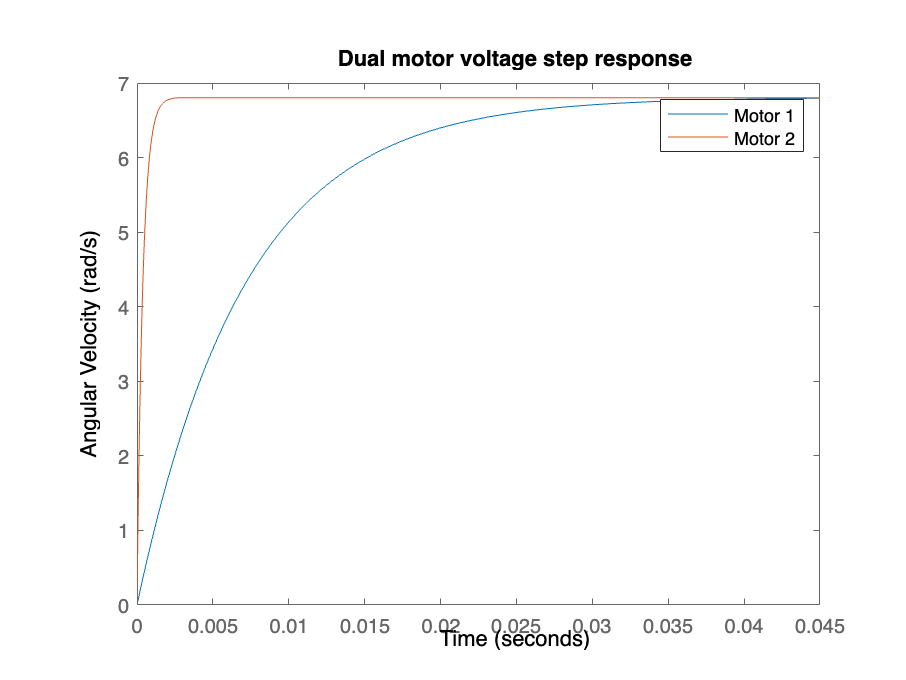

plant_phase = rad2deg(angle(evalfr(m1,wc*1i)))

plant_gain = norm(evalfr(m1, wc*1i))
plant_phase_margin = plant_phase - (-180); % Formula for phase margin, the result should be a positive number, as the system is stable.

Let's say we want 90 degrees of phase margin to dampen the motor response. How much phase margin does the controller have to provide?

desired_pm = 90;
controller_phase = desired_pm-plant_phase_margin

### Lead compensator

Increasing the lead phase results in more aggressive damping.

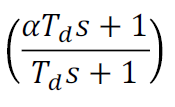

lead_phase = 40 % Close to controller phase. Units: deg

plant_phase = -125.4417

alpha = (-1-sind(lead_phase))/(sind(lead_phase)-1) %pick an alpha that gives us desired phase

plant_gain = 0.0046

Td1 = 1/(wc*sqrt(alpha)); %center lead at crossover
lead = tf([alpha*Td1 1],[Td1, 1]);

### Proportional controller

Just a gain Kp.

Kp1 = 1/(plant_gain*sqrt(alpha)) % Makes the system have unity gain

Incorrect use of '=' operator. Assign a value to a variable using '=' and compare values for equality using '=='.

pid1 = Kp1*lead;

controller_phase = 35.4417

Plot the controller to make sure it makes sense

figure;

lead_phase = 40

bode(lead);

alpha = 4.5989

hold on;
bode(pid1);
legend("Lead", "Lead-Proportional");
title("Motor 1 Lead Compensator")
hold off;

Plot the controller and the compensated plant to make sure it makes sense

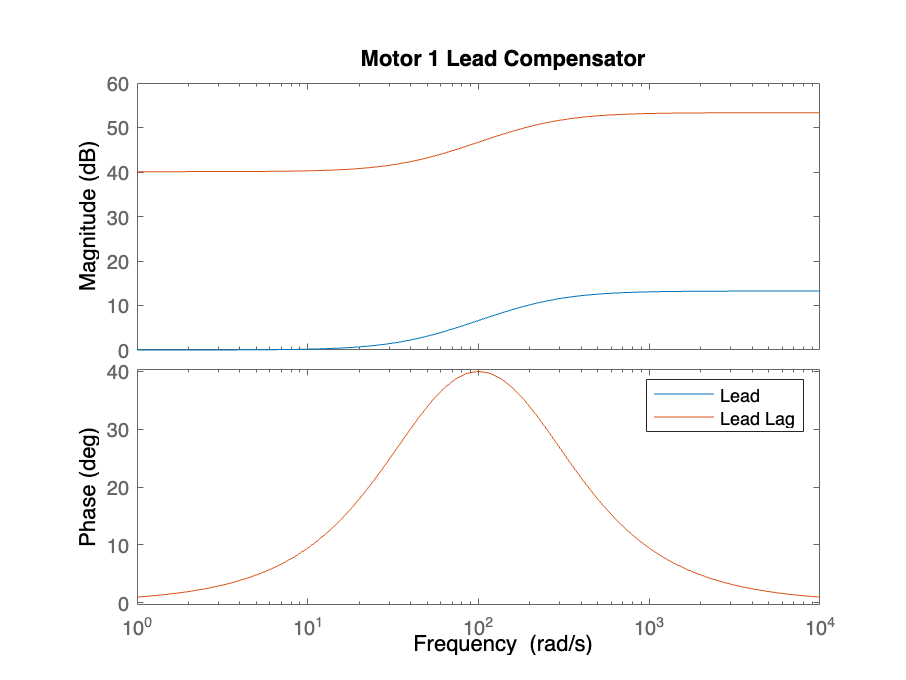

RR1 = pid1*m1;
figure;
hold on;
bode(pid1);
bode(m1);
bode(RR1);
title("Motor 1 Controller");
legend("Lead-Proportional Controller", "Motor Model", "Combined Motor and Controller");
hold off;

Check the phase margin at crossover

margin(RR1)

### Time domain

Let's check the step responses to make sure they are acceptable

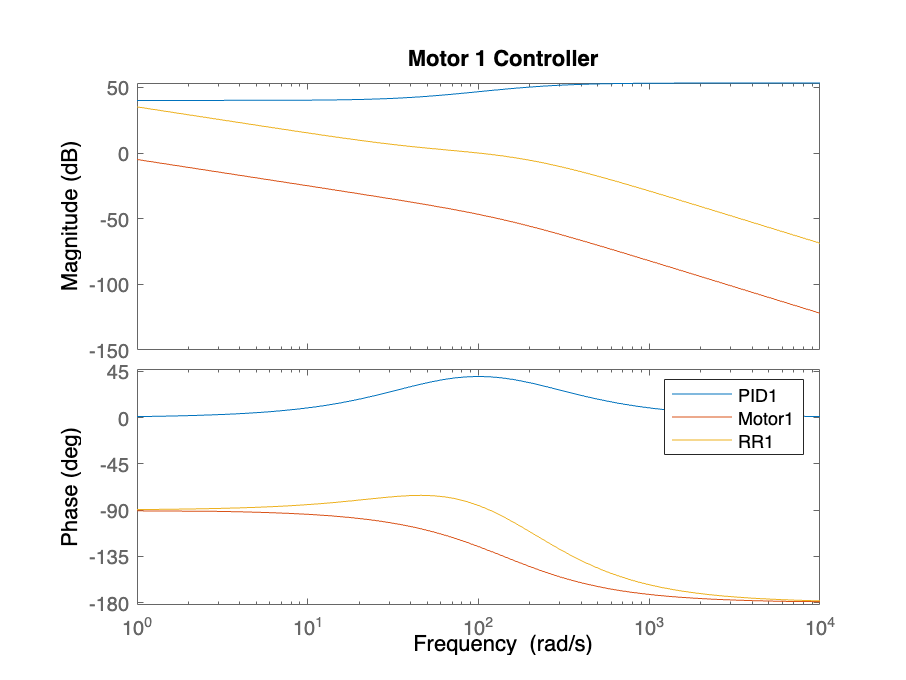

CL1 = feedback(RR1,1);
ControlEffort = feedback(pid1,m1);

step(CL1);
title("Motor 1 Position Step response");
ylabel("Angle (rad)")
figure;
step(ControlEffort)

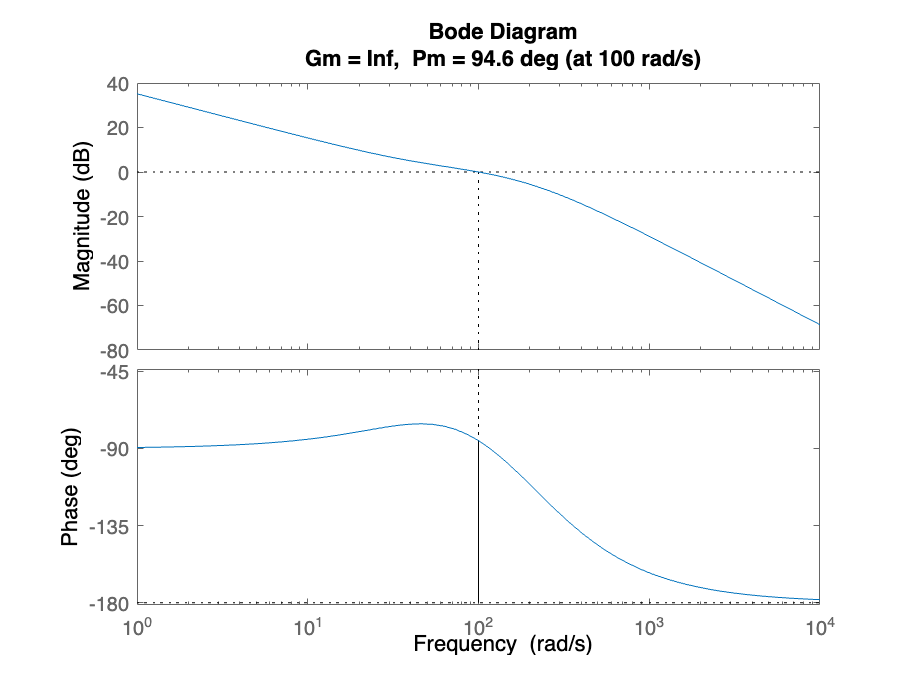

title("Motor 1 Voltage Step Response")
ylabel("Voltage (v)")

Notice the voltage requirement is comically high. What if we used a smoother step?

First we generate the "step",

sigmoidDuration = 0.2; %seconds
finalTime = 2; %seconds
finalValue = 1; %radian
stepSize = 0.001; %seconds
[t, stepInput] = generateSigmoidStepInput(sigmoidDuration, stepSize, finalTime, finalValue);

Then we simulate the response to it.

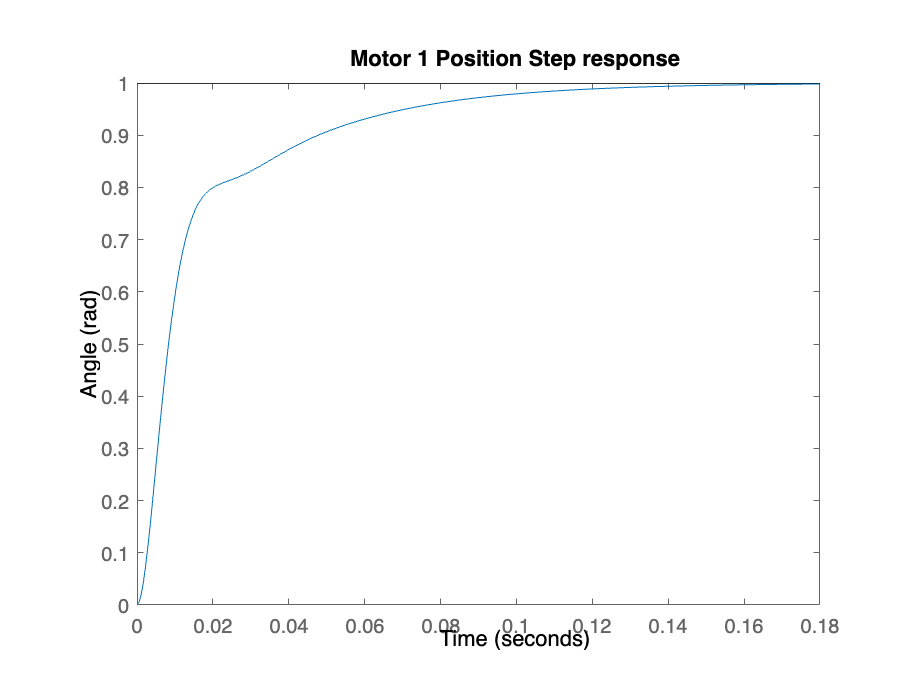

lsim(CL1, stepInput, t);

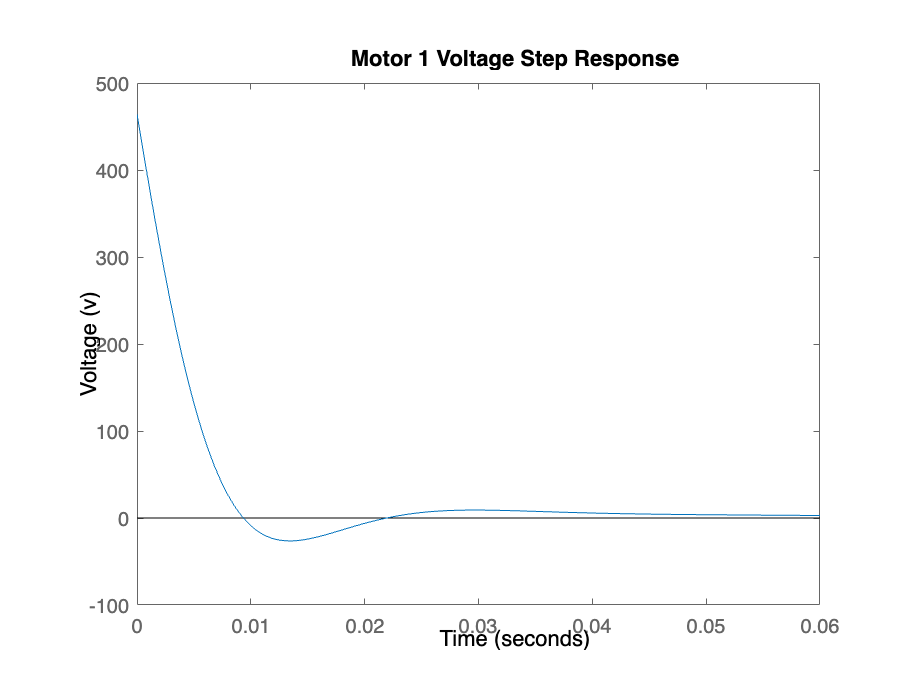

title(" Motor 1 Position response to sigmoid step input");
xlabel("Time (s)");
ylabel("Position (rad)");


lsim(ControlEffort, stepInput, t);
title("Motor 1 Voltage response to sigmoid step input");
xlabel("Time (s)");
ylabel("Voltage (v)")

## Controller 2 design time!

We are going to design a controller for the second joint.

Let's pick a conservative crossover frequency.

wc2 = 70;

How does the plant look without compensation?

plant_phase2 = rad2deg(angle(evalfr(m2,wc2*1i)))
plant_gain2 = norm(evalfr(m2, wc2*1i))
plant_phase_margin2 = plant_phase2 - (-180);

Let's say we want 90 degrees of phase margin to dampen the motor response. How much phase margin does the controller have to provide?

desired_pm2 = 90;
controller_phase2 = desired_pm2-plant_phase_margin2 % Given this result, is a lead compensator required?

### Proportional controller

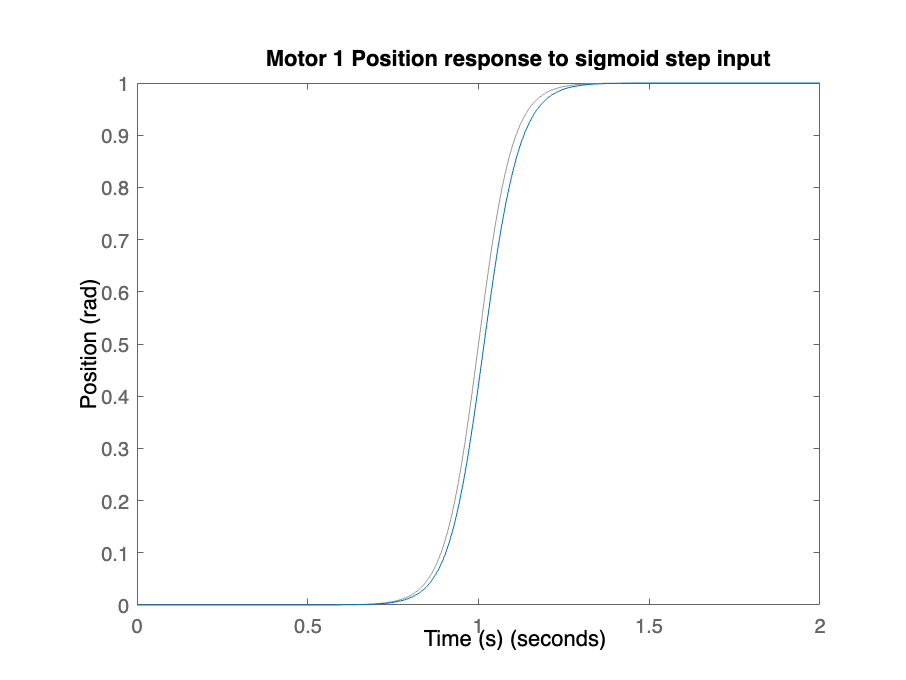

Kp2 = 1/(plant_gain2) % Makes the system have unity gain
pid2 = Kp2;

Plot the controller and the compensated plant to make sure it makes sense

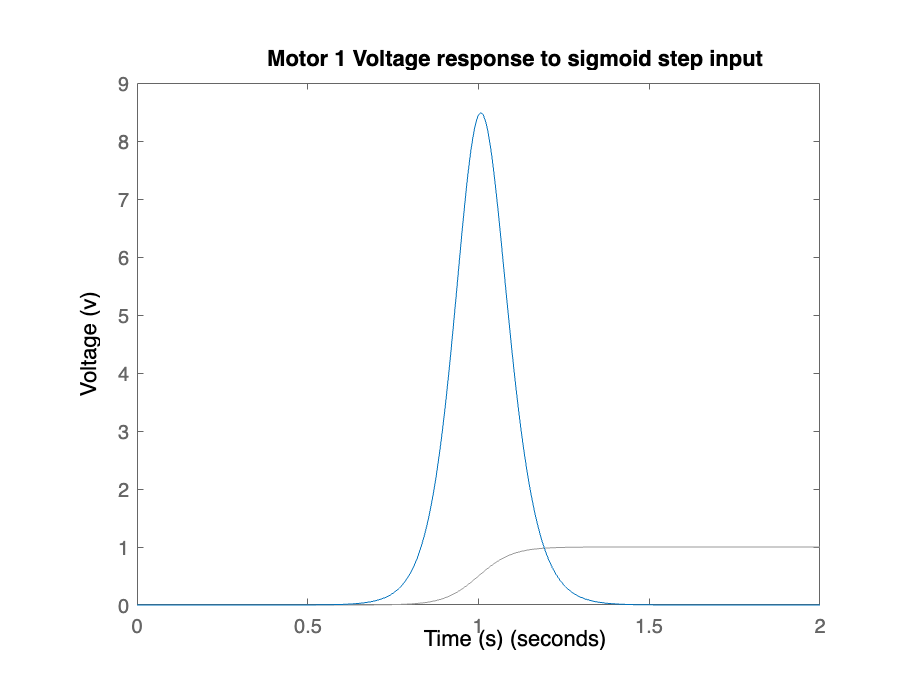

RR2 = pid2*m2;
figure;
hold on;
bode(m2);

bode(RR2);
title("Motor 2 Controller");
legend("Motor Model", "Combined Motor and Controller");
hold off;

Check the phase margin at crossover

margin(RR2)

### Time domain

Let's check the step responses to make sure they are acceptable

CL2 = feedback(RR2,1);

plant_phase2 = -91.5395

ControlEffort2 = feedback(pid2,m2);

plant_gain2 = 0.0081


step(CL2);
title("Motor 2 Position Step response");
ylabel("Angle (rad)")

controller_phase2 = 1.5395

figure;
step(ControlEffort2)

Kp2 = 123.4359

title("Motor 2 Voltage Step Response")
ylabel("Voltage (v)")

Notice the voltage requirement is comically high. What if we used a smoother step?

First we generate the "step"

sigmoidDuration = 0.2; %seconds
finalTime = 2; %seconds
finalValue = 1; %radian
stepSize = 0.001; %seconds
[t, stepInput] = generateSigmoidStepInput(sigmoidDuration, stepSize, finalTime, finalValue);

Then we simulate the response to it

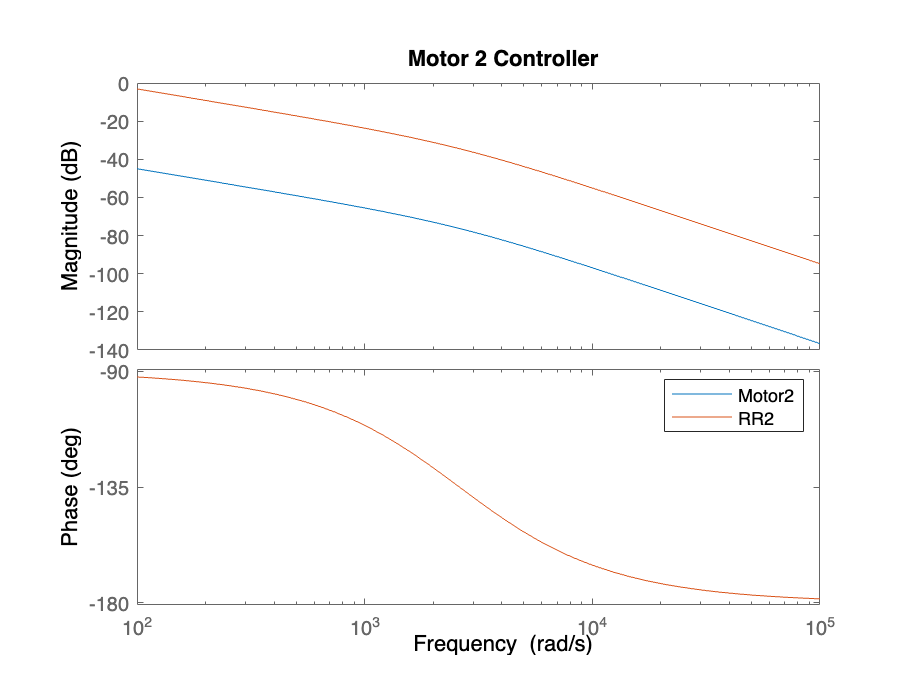

lsim(CL2, stepInput, t);
title("Motor 2 Position response to sigmoid step input");
xlabel("Time (s)");

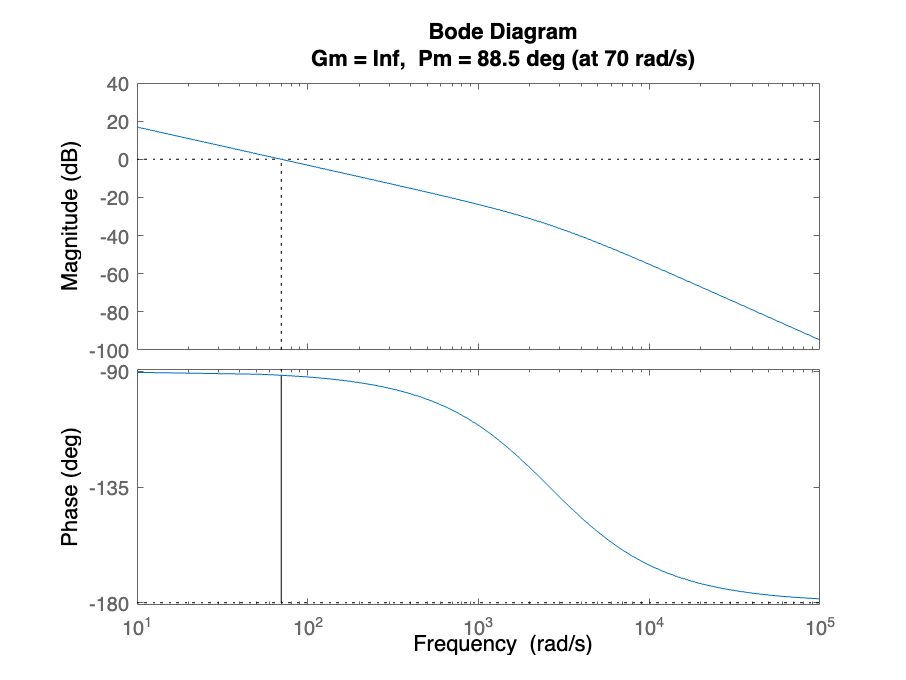

ylabel("Position (rad)");


lsim(ControlEffort2, stepInput, t);
title("Motor 2 Voltage response to sigmoid step input");
xlabel("Time (s)");
ylabel("Voltage (v)")

# Gainz

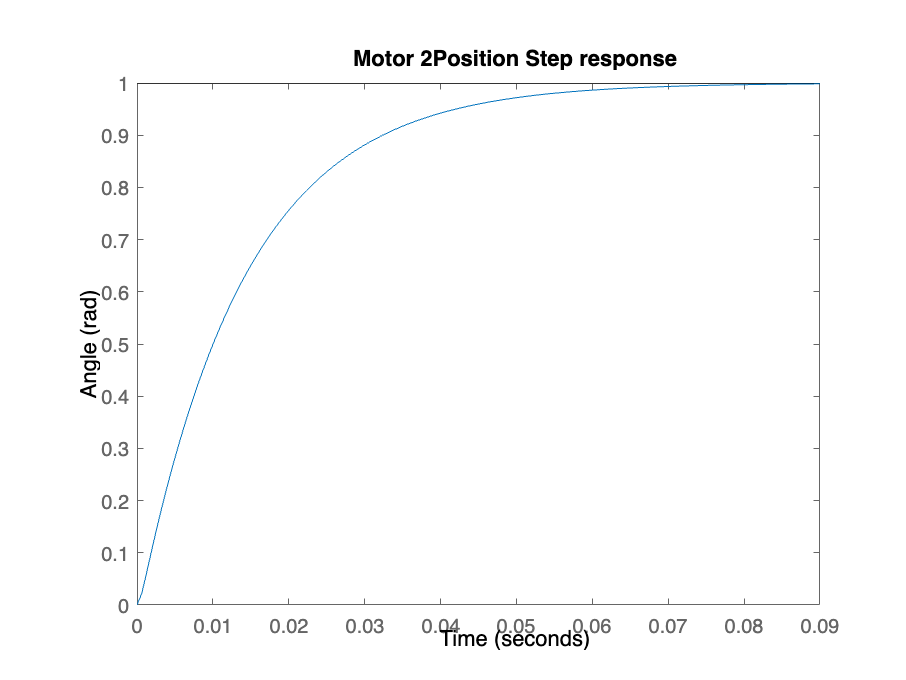

% Motor 1 (base joint)
Kp1_final = Kp1/12 % Scale proportional gain down by motor voltage
alpha
Td1

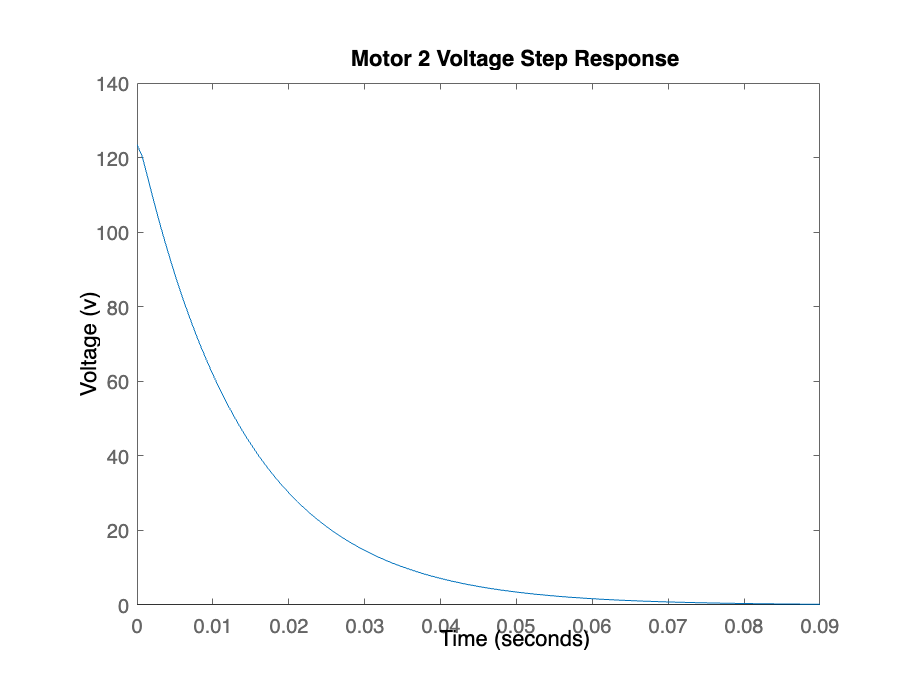


% Motor 2 (elbow joint)
Kp2_final = Kp2/12 % Scale proportional gain down by motor voltage


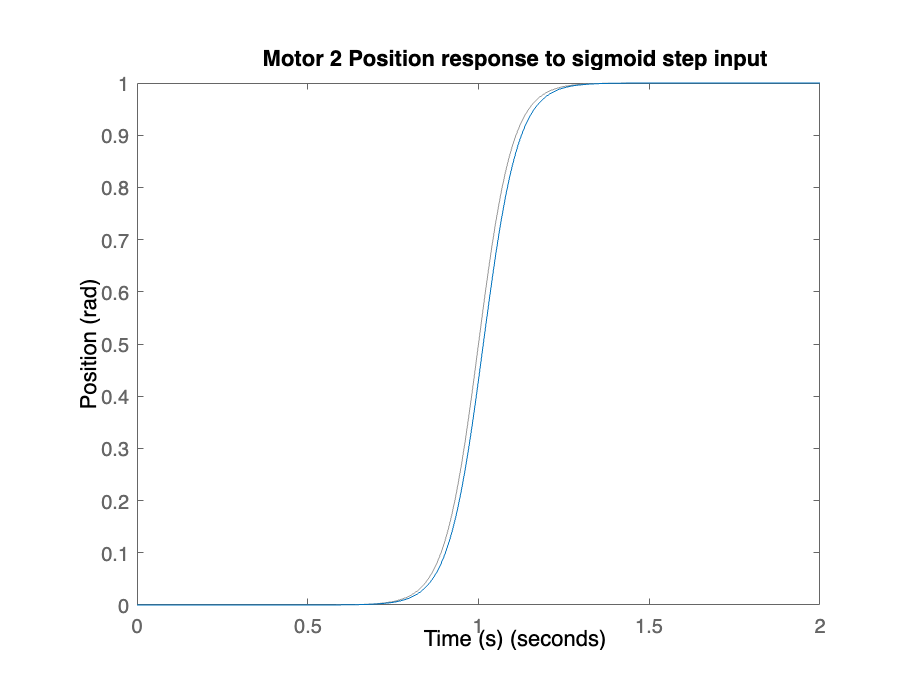

function model = generateMotorModel(I, k, B)
    a1 = I/k;
    a2 = B/k;
    model = tf(1, [a1, a2, 0]);
end

function [t, stepInput] = generateSigmoidStepInput(transitionDuration, dt, endTime, finalValue)
    % Generate time vector
    t = 0:dt:endTime;
    

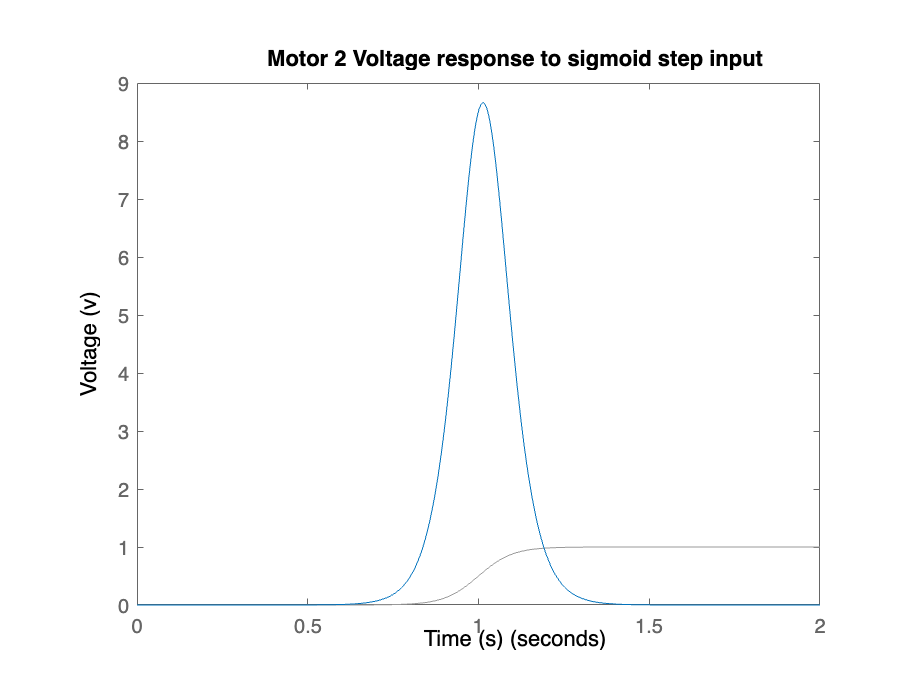

    % Calculate transition start and end times
    % Assuming transition is centered in the time interval
    transitionStart = (endTime - transitionDuration) / 2;
    transitionEnd = (endTime + transitionDuration) / 2;
    

    % Steepness of the transition
    % Adjust k for a sharper or smoother transition
    k = 4 / transitionDuration; 

Kp1 = 100.8924

    
    % Generate sigmoid step input

alpha = 4.5989

    stepInput = finalValue ./ (1 + exp(-k * (t - (transitionStart + transitionEnd) / 2)));

Td1 = 0.0047

end


Kp2 = 123.4359

function [x, y] = forwardKinematics(theta1, theta2)
    L_HOLE = 2.4; % distance between large holes in cm
    L1 = L_HOLE * 7; % Length of the first arm in cm
    L2 = L_HOLE * 9; % Length of the second arm in cm
    
    % Calculate the position in task space
    x = L1*cos(theta1) + L2*cos(theta1 + theta2);
    y = L1*sin(theta1) + L2*sin(theta1 + theta2);
end

function [theta1, theta2] = inverseKinematics(x, y)
    L_HOLE = 2.4; % distance between large holes in cm
    L1 = L_HOLE * 7; % Length of the first arm in cm
    L2 = L_HOLE * 9; % Length of the second arm in cm
    
    % Calculate joint angles from task space coordinates
    x2 = x.^2;
    y2 = y.^2;
    sumL = L1 + L2;
    diffL = L1 - L2;
    
    theta2 = 2*atan2(sqrt(sumL.^2 - (x2 + y2)), sqrt(x2 + y2 - diffL.^2));
    theta1 = atan2(y, x) - atan2(L2*sin(theta2), L1 + L2*cos(theta2));
    
    % Normalizing angles to [-pi/2, pi/2]
    theta1 = atan2(sin(theta1), cos(theta1));
    theta2 = atan2(sin(theta2), cos(theta2));
end




